num_c = [0.7555];
den_c = [ 1 13.87 34.91];
tf_t = tf( num_c, den_c)

tf_t =
 
         0.7555
  ---------------------
  s^2 + 13.87 s + 34.91
 
Continuous-time transfer function.
Model Properties


tf_t_closed = feedback( tf_t, 1)

tf_t_closed =
 
         0.7555
  ---------------------
  s^2 + 13.87 s + 35.67
 
Continuous-time transfer function.
Model Properties


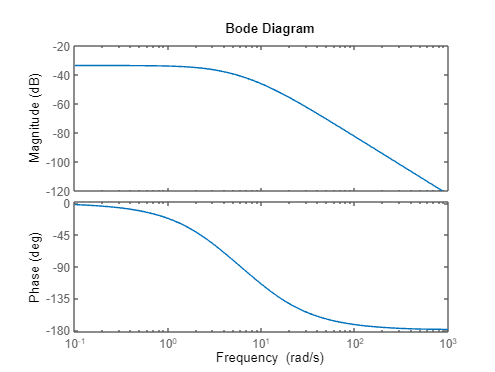


bode(tf_t_closed)

% Calculate and display the margins
[GM, PM, Wcg, Wcp] = margin(tf_t)

GM = Inf

PM = Inf

Wcg = Inf

Wcp = NaN

K_p = 0.02163;
%%With Kv
num_c = [0.7555];
den_c = [ 1 13.87 34.91];
tf_t = tf( num_c, den_c)

tf_t =
 
         0.7555
  ---------------------
  s^2 + 13.87 s + 34.91
 
Continuous-time transfer function.
Model Properties


num_c = [184.83];
den_c = [1 0];
tf_c = tf( num_c, den_c)

tf_c =
 
  184.8
  -----
    s
 
Continuous-time transfer function.
Model Properties


sample_time = 0.01;
tf_d = c2d( tf_c, sample_time, 'tustin')

tf_d =
 
  0.9242 z + 0.9242
  -----------------
        z - 1
 
Sample time: 0.01 seconds
Discrete-time transfer function.
Model Properties



tf_full = series( tf_c, tf_t)

tf_full =
 
            139.6
  -------------------------
  s^3 + 13.87 s^2 + 34.91 s
 
Continuous-time transfer function.
Model Properties


tf_full_closed = feedback( tf_full, 1)

tf_full_closed =
 
                139.6
  ---------------------------------
  s^3 + 13.87 s^2 + 34.91 s + 139.6
 
Continuous-time transfer function.
Model Properties


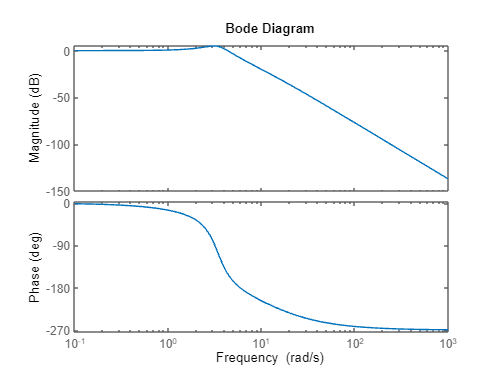

bode(tf_full_closed)

% Calculate and display the margins
[GM, PM, Wcg, Wcp] = margin(tf_full_closed)

GM = 2.4675

PM = 30.0350

Wcg = 5.9085

Wcp = 4.3340

%%let use move the gain margine to about 50 degrees
num_phase = [3*184.83 1*184.83];
den_phase = [1 0];
tf_phase = tf( num_phase, den_phase)

tf_phase =
 
  554.5 s + 184.8
  ---------------
         s
 
Continuous-time transfer function.
Model Properties


tf_d = c2d( tf_phase, sample_time, 'tustin')

tf_d =
 
  555.4 z - 553.6
  ---------------
       z - 1
 
Sample time: 0.01 seconds
Discrete-time transfer function.
Model Properties


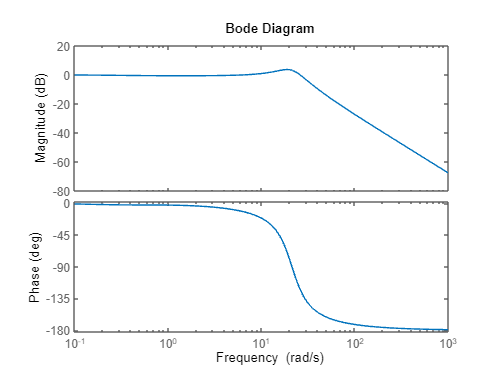


tf_full = series( tf_phase, tf_t);
tf_full_closed = feedback( tf_full, 1);
bode(tf_full_closed)

% Calculate and display the margins
[GM, PM, Wcg, Wcp] = margin(tf_full_closed)%%At this point the goal is acheived

GM = Inf

PM = 57.2501

Wcg = Inf

Wcp = 25.9987

%%let use move the gain margine to about 50 degrees
num_phase = [0.025*184.83 5.005*184.83 1*184.83];
den_phase = [1 0];
tf_phase = tf( num_phase, den_phase)

tf_phase =
 
  4.621 s^2 + 925.1 s + 184.8
  ---------------------------
               s
 
Continuous-time transfer function.
Model Properties


tf_d = c2d( tf_phase, sample_time, 'tustin')

tf_d =
 
  1850 z^2 - 1846 z
  -----------------
       z^2 - 1
 
Sample time: 0.01 seconds
Discrete-time transfer function.
Model Properties


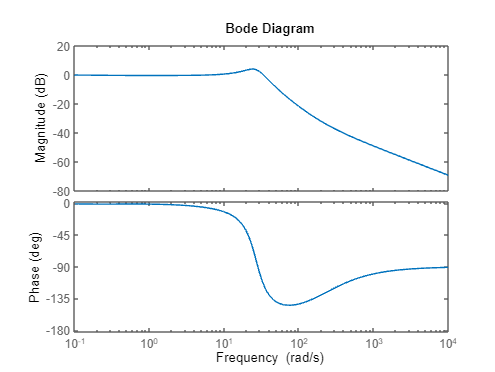

tf_full = series( tf_phase, tf_t);
tf_full_closed = feedback( tf_full, 1);
bode(tf_full_closed)

% Calculate and display the margins
[GM, PM, Wcg, Wcp] = margin(tf_full_closed)

GM = Inf

PM = 64.4406

Wcg = NaN

Wcp = 33.7318

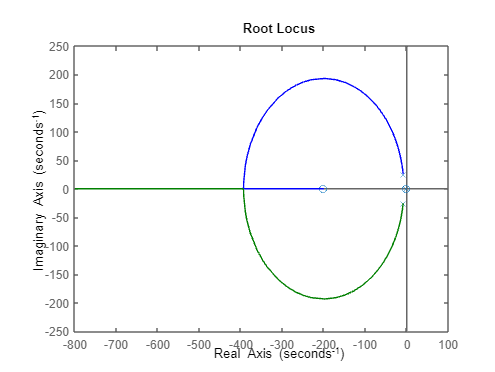

rlocus(tf_full_closed)